## Lab 1

    In this part of the lab, we investigate the relationship between a probability and a 'sigma' value. A Gaussian (normal) distribution is a probability density function (pdf) parameterized by 2 variables, sigma and mu, where sigma is the standard deviation and mu is the mean of the distribution.

Below, we explore the effects of varying these parameters on the shape of the pdf.

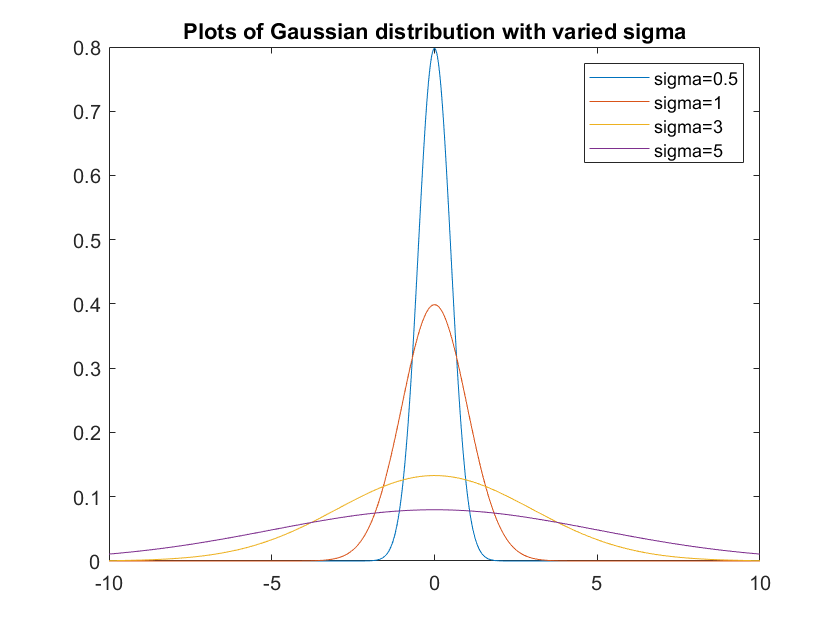

x = linspace(-10,10,1000);
plot(x,normpdf(x,0,0.5))
title('Plots of Gaussian distribution with varied sigma')
hold on
plot(x,normpdf(x,0,1))
plot(x,normpdf(x,0,3))
plot(x,normpdf(x,0,5))
legend('sigma=0.5','sigma=1','sigma=3','sigma=5')
hold off

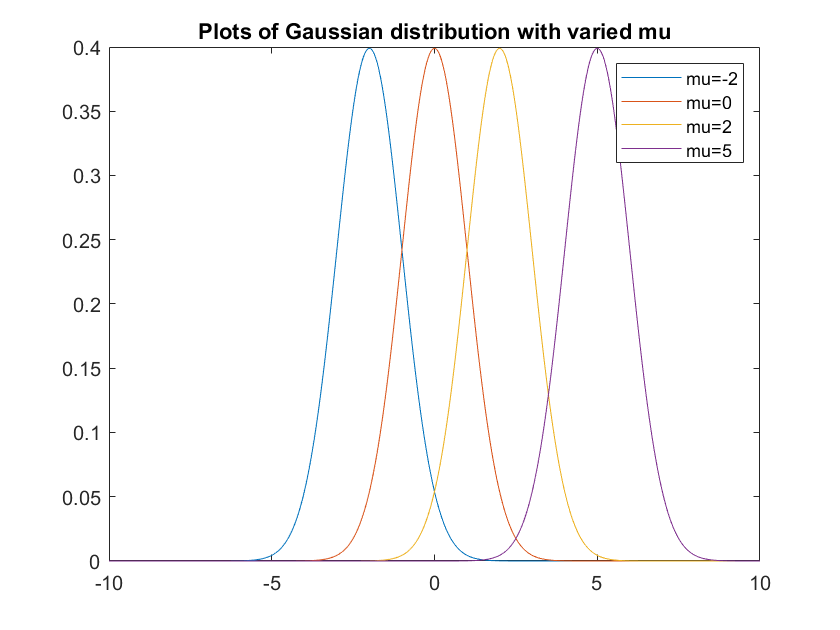

plot(x,normpdf(x,-2,1))
title('Plots of Gaussian distribution with varied mu')
hold on
plot(x,normpdf(x,0,1))
plot(x,normpdf(x,2,1))
plot(x,normpdf(x,5,1))
legend('mu=-2','mu=0','mu=2','mu=5')
hold off

As observed above, increasing sigma shortens and widens the pdf, while increasing mu shifts the pdf to the right by mu.

In class, we integrated the upper tail of pdfs to determine the probability that our background gave us a measurement that was as signal-like or more signal-like than a candidate measured signal. Here we do the same, integrating the standard normal distribution (mu = 0, sigma = 1) to determine the area under the curve that lies to the right of a given sigma value, or displacement from the mean.

x_sigma = [0; 1; 2; 3];
p = 1-normcdf(x_sigma);
disp(table(x_sigma,p,'VariableNames',{'Displacement from mean (in units of sigma)','Probability'}))

    Displacement from mean (in units of sigma)    Probability
    __________________________________________    ___________

                        0                                0.5 
                        1                            0.15866 
                        2                            0.02275 
                        3                          0.0013499 



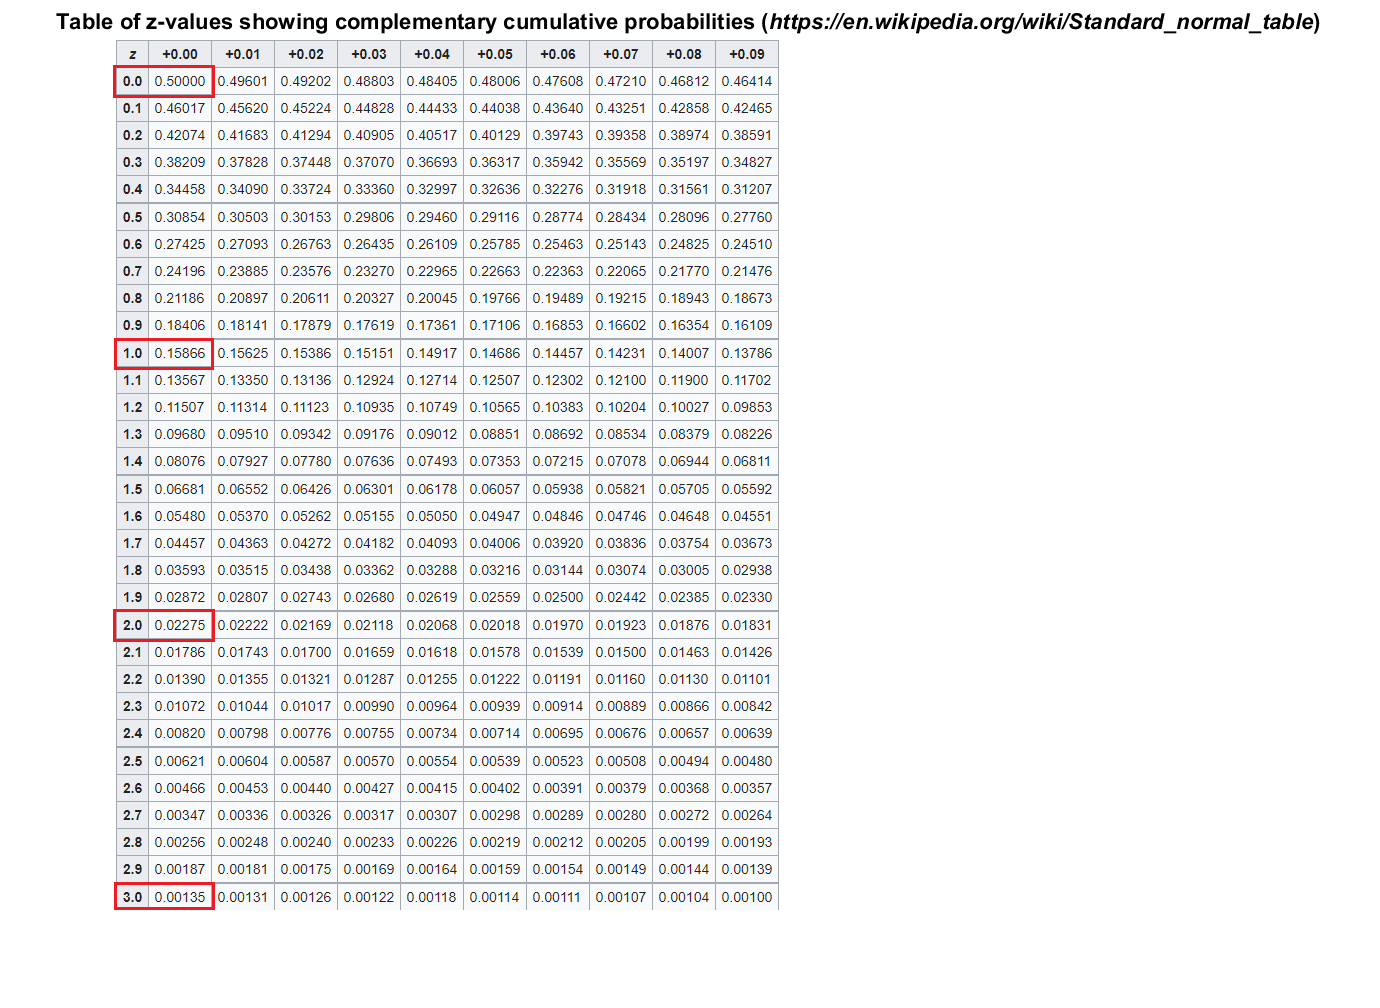

imshow('z_table.png')
title(['Table of z-values showing complementary cumulative probabilities ' ...
    '({\ithttps://en.wikipedia.org/wiki/Standard\_normal\_table})']);

Comparing probabilities in the z-table with those computed, it is evident that they match and our computed values are correct.

Now we do the inverse. Our goal is to compute the sigma value (or displacement away from the mean) given a probability.

p_given = [0.15866;0.30854;0.02275;0.00256;0.00135];
x_sigma = norminv(p_given);
disp(table(x_sigma,p_given,'VariableNames',{'Displacement from mean (in units of sigma)','Probability'}))

    Displacement from mean (in units of sigma)    Probability
    __________________________________________    ___________

                     -0.99998                       0.15866  
                     -0.49999                       0.30854  
                           -2                       0.02275  
                      -2.7994                       0.00256  
                           -3                       0.00135  



Note that the probabilities and associated sigma values match those in the z-table above up to a minus sign. The reason for this is as follows: Matlab integrates the pdf from the left to get the cumulative probability. When we input the probability into the function, Matlab integrates the pdf until it reaches the value of that probability, and returns the x-value (also the sigma value in this case) at that point. In essence, our statistical question requires us to integrate the right tail while Matlab integrates the left tail, so the sigma values are on different sides of the mean.

To deal with this, instead of giving the Matlab function the desired probability *p*, I will give it *1 - p*. This flips the sign of the sigma value and works for any probability.

p_given = [0.15866;0.30854;0.02275;0.00256;0.00135];
x_sigma = norminv(1-p_given);
disp(table(x_sigma,p_given,'VariableNames',{'Displacement from mean (in units of sigma)','Probability'}))

    Displacement from mean (in units of sigma)    Probability
    __________________________________________    ___________

                     0.99998                        0.15866  
                     0.49999                        0.30854  
                           2                        0.02275  
                      2.7994                        0.00256  
                           3                        0.00135  



The sign of the sigma values is now correct.

This section examines another continuous analytic distribution - the Chi-Squared distribution.

Definition

$\chi^2 \equiv \sum_{i=1}^v Y_i^2$ for each $Y_i$ sampled from a standard normal distribution.

$v$ is the number of degrees of freedom and is the only parameter in this distribution. Below we plot a Chi-Squared distributions with varying degrees of freedom.

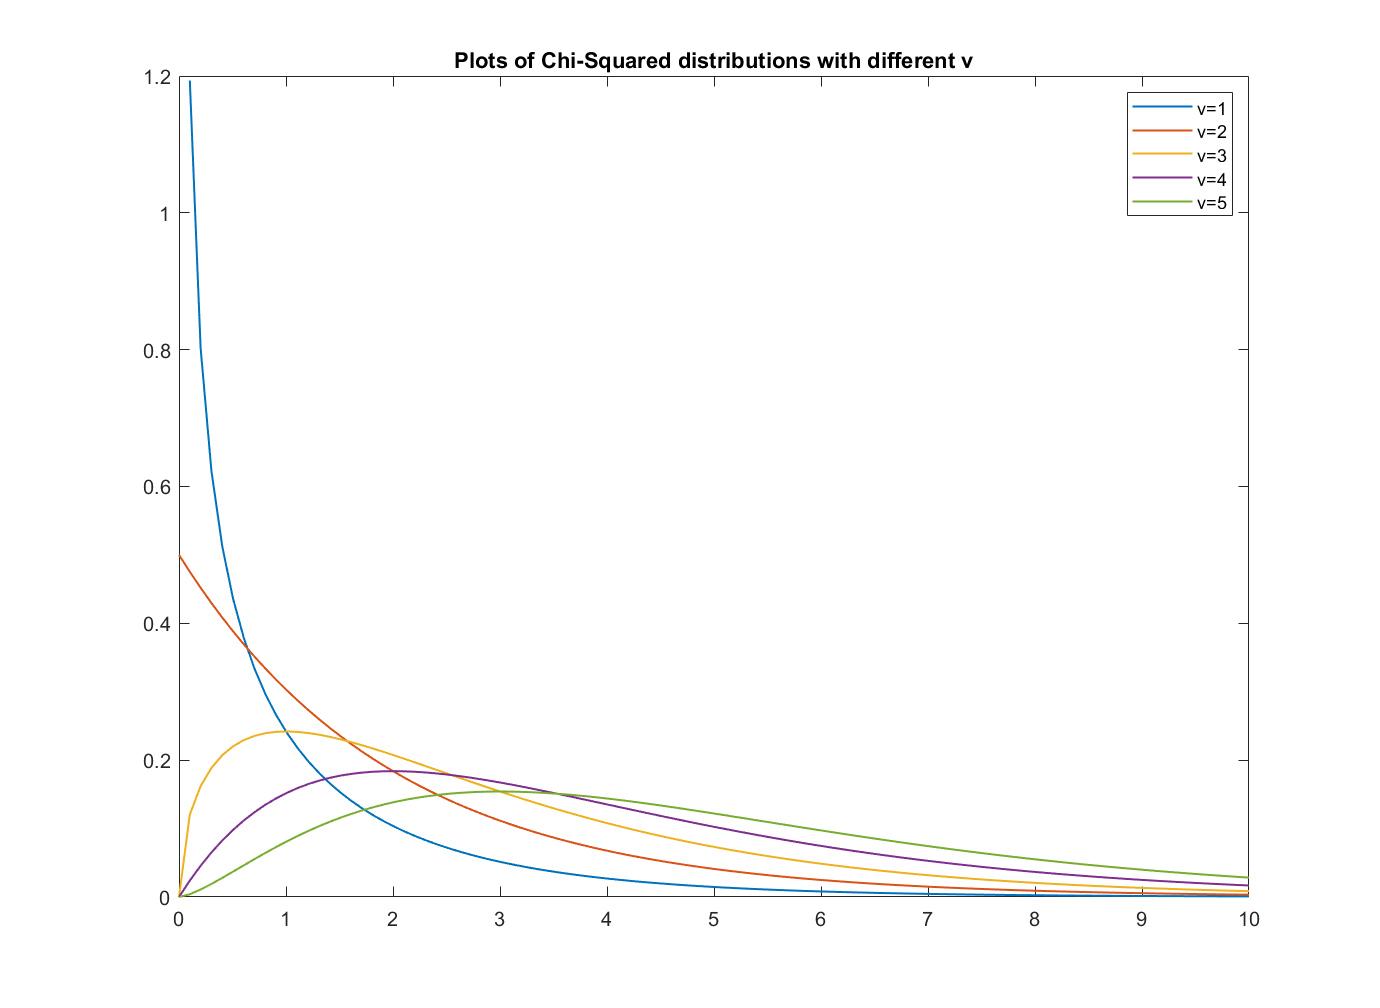

x = linspace(0,10,100);
plot(x,chi2pdf(x,1),"LineWidth",1)
title('Plots of Chi-Squared distributions with different v')
hold on
plot(x,chi2pdf(x,2),"LineWidth",1)
plot(x,chi2pdf(x,3),"LineWidth",1)
plot(x,chi2pdf(x,4),"LineWidth",1)
plot(x,chi2pdf(x,5),"LineWidth",1)
legend('v=1','v=2','v=3','v=4','v=5')
hold off

Note that this distribution has no negative values. This makes sense because we obtained it by squaring values from a standard normal distribution. For $v\le 2$, the pdf decreases monotomically. Recall that the distribution is obtained by taking the sum of squares from a standard normal distribution. The probability of picking a value near zero is high, and when squared, any value less than 1 in magnitude gets closer to zero. For one or two degrees of freedom, the high probability of picking a small number dominates. As we increases the degrees of freedom, the sum dominates (ie. the addition of small values outweighs the squaring of a single small value). The distribution therefore develops a peak further and further right and appears to spread out more.

Next we simulate data that follows this distribution and plot it in the histogram below. We will use $v=4$.

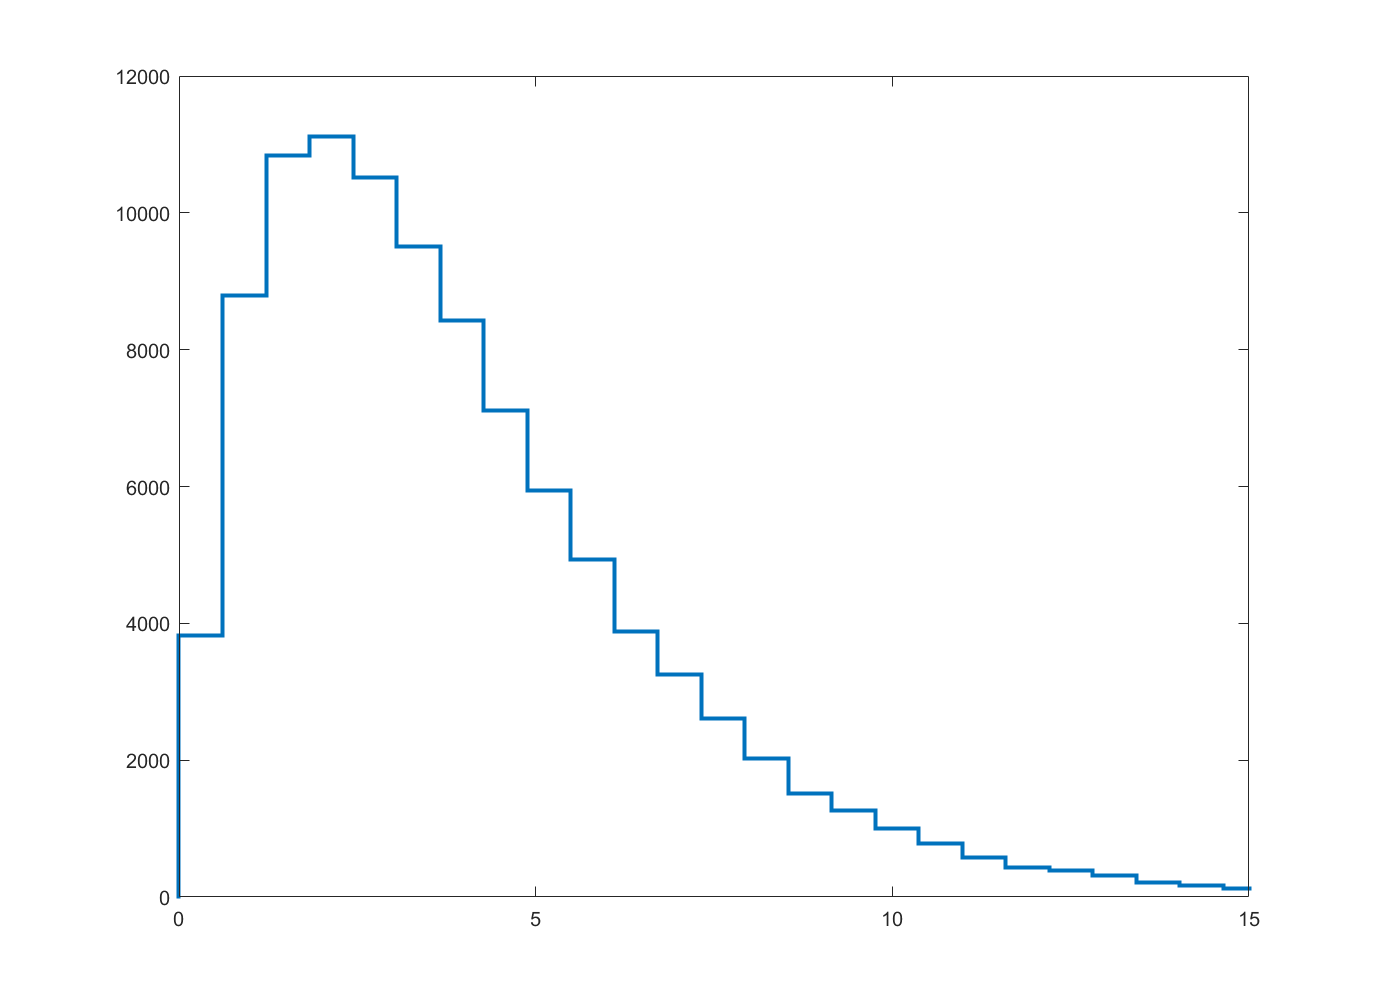

v = 4;
d = random('Chisquare', v, [1,100000]);
histogram(d,50,'DisplayStyle',"stairs",'LineWidth',2)
xlim([0,15])

The histogram plotted above looks similar in shape to the continuous pdf. We overlay the two in the plot below.

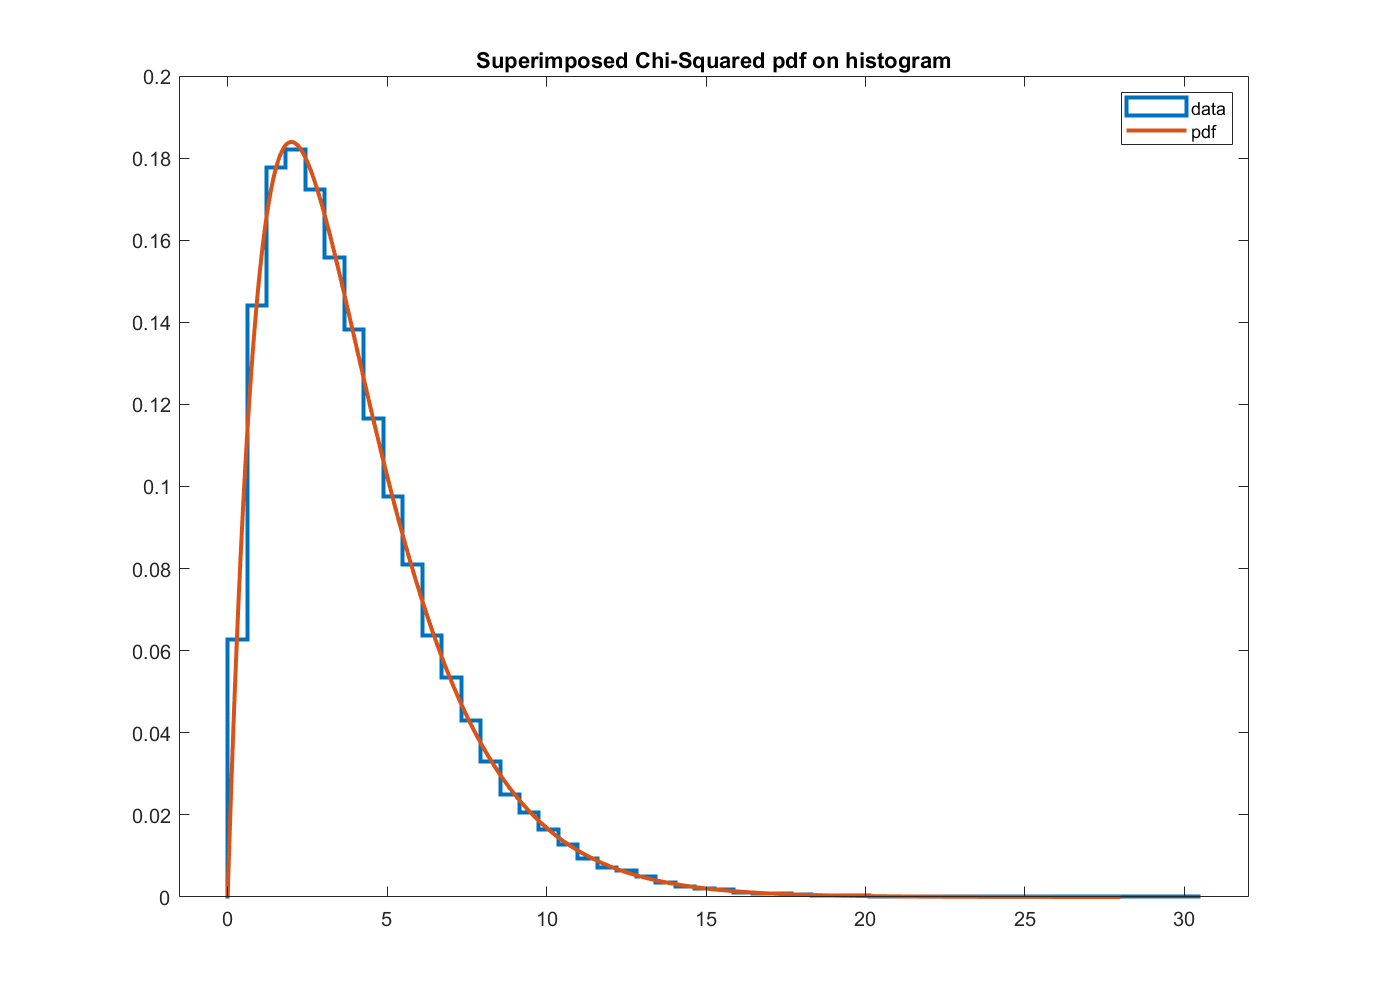

histogram(d,50,'DisplayStyle',"stairs",'LineWidth',2,"Normalization","pdf")
hold on
x = linspace(0,28,500);
pd = chi2pdf(x,v);
%pd = makedist("Gamma","a",v/2,"b",2);
plot(x,pd,"LineWidth",2);
title('Superimposed Chi-Squared pdf on histogram')
legend('data','pdf')
hold off

As in the homework, we can plot the distributions against a log scale on the y-axis as shown below.

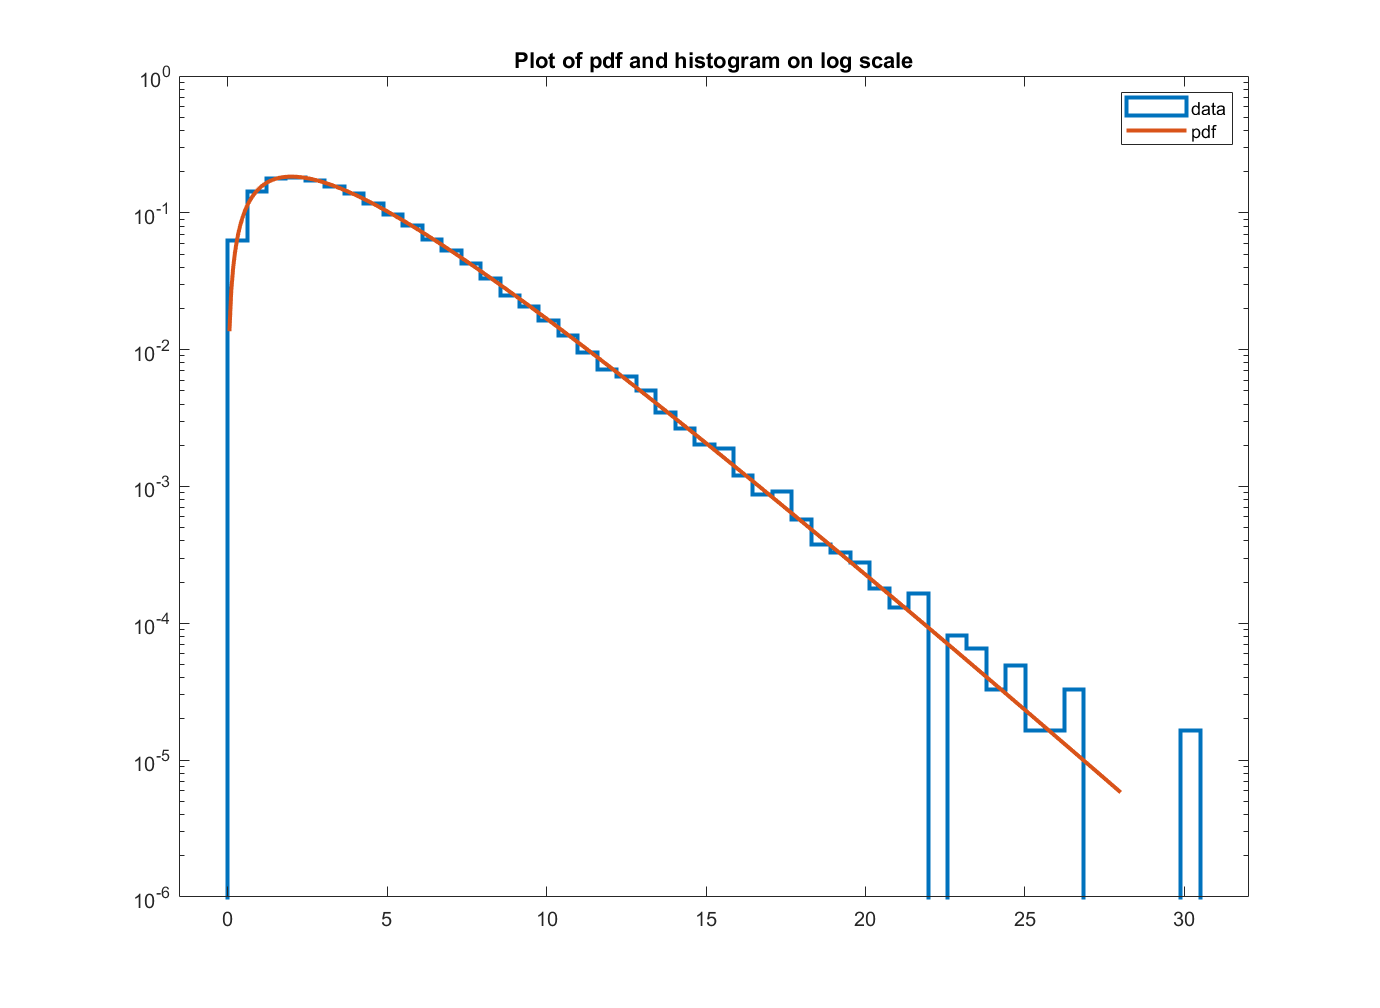

histogram(d,50,'DisplayStyle',"stairs",'LineWidth',2,"Normalization","pdf")
hold on
%pd = chi2pdf(x,v);
plot(x,pd,"LineWidth",2);
title('Plot of pdf and histogram on log scale')
legend('data','pdf')
set(gca,'YScale','log')
hold off

Outliers in the histogram are more prominent in the log plot, but it follows the Chi-Squared distribution nicely overall.

### Hypothetical

    Now imagine we have background signal-free data that follows the distribution above. Suppose I have a measurement for which I need to determine the 'sigma' value. I outline below the steps below to determine this.

Value of measurement = 12

Statistical Question

If the signal-free data has a Chi-Squared distribution, what is the probability that the background gave me a measurement as signal-like or more signal-like than what I observed?

Here we define more signal-like to be a higher value.

Mathematical Integral


$$\mathrm{Probability}=\int_{12}^{\infty } \mathrm{pdf}\left(x\right)\mathrm{dx}=\int_{12}^{\infty } \frac{x^{\frac{v-2}{2}} e^{-\frac{x}{2}} }{2^{\frac{v}{2}} \;\Gamma \left(v/2\right)}\mathrm{dx}$$


While this integral looks enticing to compute manually, we instead make use of Matlab's statistics functions to calculate it.

p_12 = cdf('Chisquare',12,4,'upper');
disp(p_12)

    0.0174



I can compare this value to values in a chi-square z-table as a sanity check.

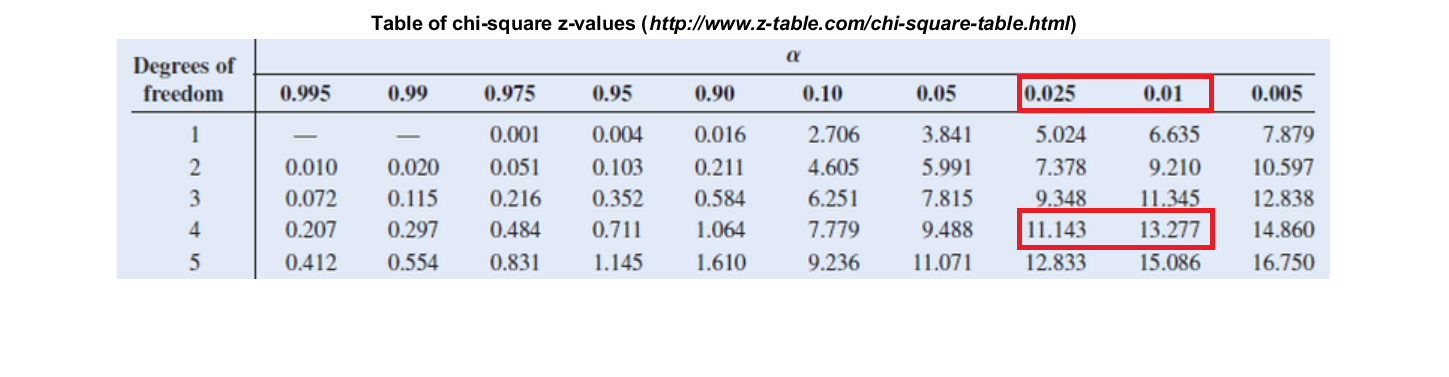

imshow('chisq_zscore.png')
title('Table of chi-square z-values ({\ithttp://www.z-table.com/chi-square-table.html})');

Our selected measurement value of 12 is between 11.143 and 13.277, and our calculated probability falls between 0.025 and 0.01. Therefore we have reason to trust our calculated probability.

Now we need to convert this probability to a sigma value. We do this below by computing the x-value for which a standard normal distribution gives the same probability.

sig_12 = norminv(1-p_12);
disp(sig_12)

    2.1118



The sigma value for a probability of 0.0174 is 2.1118. This corresponds with the z-table for the standard normal distribution above.

**RESULT: **$P\left(x>12\right)=2\ldotp 1118\;\sigma$

Explore

What happens if we vary the hypothetical measurement values? How do the sigma values change, and is there a pattern to it? We do this below for a range of measurement values.

x_range = [10:0.5:30]';
p_range = cdf('Chisquare',x_range,4,'upper');
sig_range = norminv(1-p_range);
disp(table(x_range,p_range,sig_range,'VariableNames',{'x','P','sigma'}))

     x          P         sigma 
    ____    __________    ______

      10      0.040428    1.7457
    10.5      0.032797    1.8412
      11      0.026564    1.9339
    11.5      0.021484     2.024
      12      0.017351    2.1118
    12.5      0.013996    2.1974
      13      0.011276    2.2809
    13.5     0.0090743    2.3626
      14     0.0072951    2.4424
    14.5     0.0058589    2.5205
      15     0.0047012    2.5971
    15.5      0.003769    2.6721
      16     0.0030192    2.7457
    16.5     0.0024166    2.8179
      17     0.0019329    2.8889
    17.5      0.001545    2.9586
      18     0.0012341    3.0272
    18.5    0.00098514    3.0947
      19    0.00078594    3.1611
    19.5    0.00062667    3.2265
      20     0.0004994    3.2909
    20.5    0.00039777    3.3543
      21    0.00031667    3.4169
    21.5    0.00025198    3.4786
      22    0.00020042    3.5395
    22

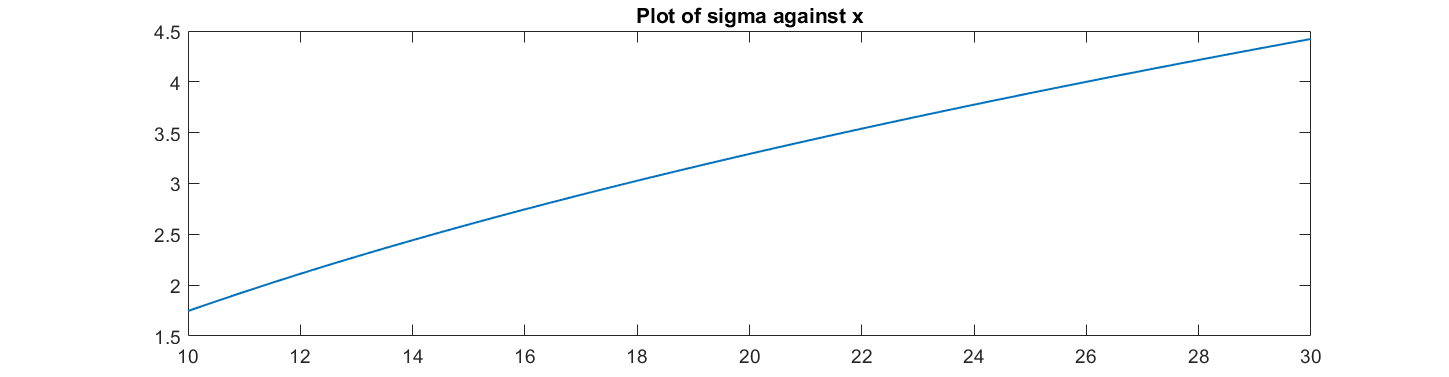

plot(x_range,sig_range,'LineWidth',1)
title('Plot of sigma against x')

The sigma value for this distribution increases more rapidly at lower x but tapers off as x increases. Although the tail of the distribution appears narrow, the fact that the sigma values taper off suggests that the tail does not converge to zero that rapidly.

### Non-continuous distributions

    In this section we study the Binomial distribution. This is a discrete probability distribution for experiments with only yes/no or true/false values. It takes parameters *n *and *p*, where in a series of *n *independent experiments, the probability of a sucessful outcome is *p* and the probability of a failure is *q = 1 - p*. 

Below are plots of Binomial distributions with different parameters.

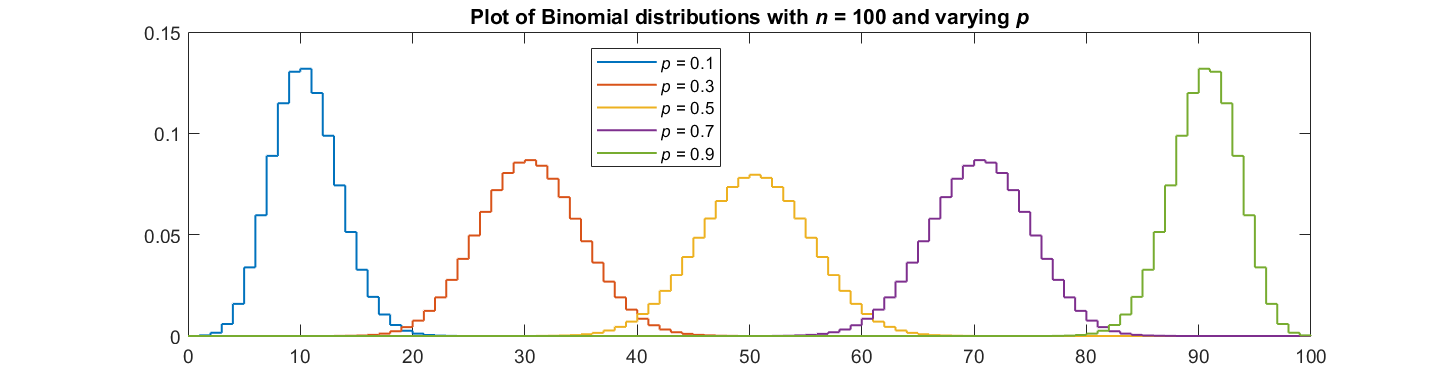

n = 100;
x = [0:n];
for p = [0.1 0.3 0.5 0.7 0.9]
    y_bino = binopdf(x,n,p);
    stairs(x,y_bino,'LineWidth',1)
    hold on
end
title('Plot of Binomial distributions with {\itn} = 100 and varying {\itp}')
legend('{\itp} = 0.1','{\itp} = 0.3','{\itp} = 0.5','{\itp} = 0.7','{\itp} = 0.9','Location','best')
hold off

The plot above shows that the distributions are symmetric about *n/2*, and they are more sharply peaked at the edges.

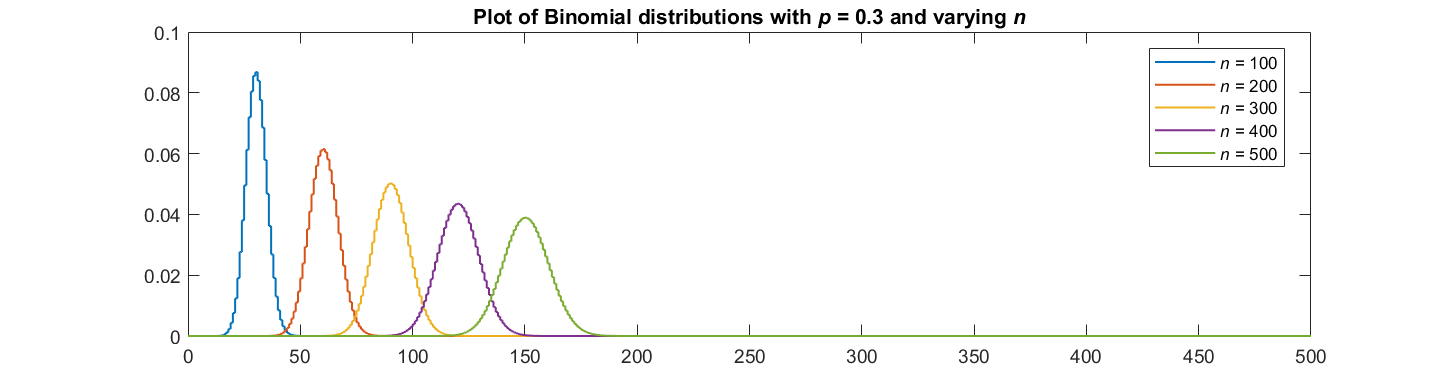

p = 0.3;
for n = [100 200 300 400 500]
    x = [0:n];
    y_bino = binopdf(x,n,p);
    stairs(x,y_bino,'LineWidth',1)
    hold on
end
title('Plot of Binomial distributions with {\itp} = 0.3 and varying {\itn}')
legend('{\itn} = 100','{\itn} = 200','{\itn} = 300','{\itn} = 400','{\itn} = 500', ...
    'Location','best')
hold off

As the number of trials increases, the distributions move right and shallow out. They are peaked at $p\times n$, which makes sense because the most instances of success should come at the point that is equal to the probability of success multiplied by the number of trials.

### Hypothetical Putting Contest

    We again go through the process of thinking of a hypothetical experiment and find the sigma value, given a particular x-value. Imagine we have a golfer, Jesse, whom we know makes a 25-foot putt 10% of the time. He decides to enter a putting contest, where the person who makes the most 25-foot putts wins the contest. In the case of a tie, the person who went earlier wins. Each person is given 20 tries. Jesse gets stuck in traffic on the way to the contest and is the last person to arrive, so he is the last to go. As he checks in to begin his turn, he notices that the highest score thus far is 5. What is the probability that Jesse wins this putting contest?

Statistical Question

For a Binomial distribution with *n = 20 *and *p = 0.1*, what is the probability that we get a value greater than 5.

Mathematical Solution


$$\mathrm{Probability}=\sum_6^{20} \mathrm{pdf}\left(x\right)=\sum_6^{20} \frac{n!}{x!\left(n-x\right)!}p^x {\left(1-p\right)}^{n-x}$$


We again use the statistical functions in Matlab to compute this value.

n = 20;
p = 0.1;
p_win = cdf('Binomial',5,n,p,'upper');
sig_win = norminv(1-p_win);
disp(table(p_win,sig_win,'VariableNames',{'P(win)','sigma'}))

     P(win)     sigma 
    ________    ______

    0.011253    2.2817



**Result: **The probability that Jesse wins is 0.011253 or 2.2817$\sigma$.

In the case of discrete probability distributions, probabilities and sigmas can only change in discrete steps. For an experiment involving binary outcomes, such as whether a photon hits a detector or not, the step sizes are larger for lower *n *and smaller for larger *n*. This means, for example, that repeating the background experiment more times makes the distribution look more like a continuous one. A measured reading can then be associated with a finer resolution of probabilities.

// Last part still to be done.